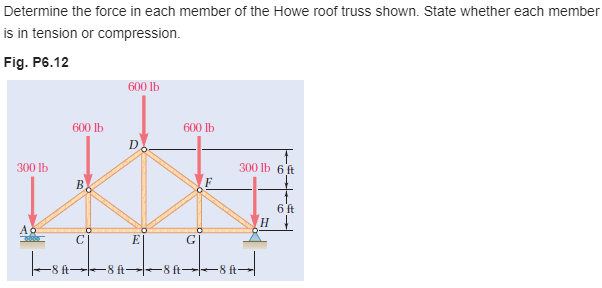

[https://www.chegg.com/homework-help/Vector-Mechanics-for-Engineers-Statics-11th-edition-chapter-6-problem-12P-solution-9780077687304](https://www.chegg.com/homework-help/Vector-Mechanics-for-Engineers-Statics-11th-edition-chapter-6-problem-12P-solution-9780077687304) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# member data

E = sym('E');
A = sym('A');
theta = atand(sym(6)/sym(8))*u.deg;

# truss

t = Truss;
t = t.add('reaction', {0 'Ray'}, [0 0]);
t = t.add('reaction', {'Rhx' 'Rhy'}, [32 0]*u.ft);
t = t.add('concentrated', [0 -300]*u.lbf, [0 0]);
t = t.add('concentrated', [0 -600]*u.lbf, [8 6]*u.ft);
t = t.add('concentrated', [0 -600]*u.lbf, [16 12]*u.ft);
t = t.add('concentrated', [0 -600]*u.lbf, [24 6]*u.ft);
t = t.add('concentrated', [0 -300]*u.lbf, [32 0]*u.ft);
t = t.add('joint', 'A', [0 0]);
t = t.add('joint', 'B', [8 6]*u.ft);
t = t.add('joint', 'C', [8 0]*u.ft);
t = t.add('joint', 'D', [16 12]*u.ft);
t = t.add('joint', 'E', [16 0]*u.ft);
t = t.add('joint', 'F', [24 6]*u.ft);
t = t.add('joint', 'G', [24 0]*u.ft);
t = t.add('joint', 'H', [32 0]*u.ft);
t = t.add('member', 'Fab', [0 0], [8 6]*u.ft);
t = t.add('member', 'Fac', [0 0], [8 0]*u.ft);
t = t.add('member', 'Fbc', [8 6]*u.ft, [8 0]*u.ft);
t = t.add('member', 'Fbd', [8 6]*u.ft, [16 12]*u.ft);
t = t.add('member', 'Fbe', [8 6]*u.ft, [16 0]*u.ft);
t = t.add('member', 'Fce', [8 0]*u.ft, [16 0]*u.ft);
t = t.add('member', 'Fde', [16 12]*u.ft, [16 0]*u.ft);
t = t.add('member', 'Fdf', [16 12]*u.ft, [24 6]*u.ft);
t = t.add('member', 'Fef', [16 0]*u.ft, [24 6]*u.ft);
t = t.add('member', 'Feg', [16 0]*u.ft, [24 0]*u.ft);
t = t.add('member', 'Ffg', [24 6]*u.ft, [24 0]*u.ft);
t = t.add('member', 'Ffh', [24 6]*u.ft, [32 0]*u.ft);
t = t.add('member', 'Fgh', [24 0]*u.ft, [32 0]*u.ft);

# solution

[us ua fs fa rs ra] = t.solve('factor'); %#ok
ua_vpa = vpa(ua, 7) %#ok

$$ua\_vpa = \left(\begin{array}{cc} u_{1} & -\frac{38400.0}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ v_{1} & 0\\ u_{2} & -\frac{7125.0}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ v_{2} & -\frac{66700.0}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ u_{3} & -\frac{28800.0}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ v_{3} & -\frac{66700.0}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ u_{4} & -\frac{19200.0}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ v_{4} & -\frac{67266.67}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ u_{5} & -\frac{19200.0}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ v_{5} & -\frac{74466.67}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ u_{6} & -\frac{31275.0}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ v_{6} & -\frac{66700.0}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ u_{7} & -\frac{9600.0}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ v_{7} & -\frac{66700.0}{A\,\text{E}}\,\mathrm{ft}\,\mathrm{lbf}\\ u_{8} & 0\\ v_{8} & 0 \end{array}\right)$$

fa

$$fa = \left(\begin{array}{cc} \mathrm{Fab} & -1500\,\mathrm{lbf}\\ \mathrm{Fac} & 1200\,\mathrm{lbf}\\ \mathrm{Fbc} & 0\\ \mathrm{Fbd} & -1000\,\mathrm{lbf}\\ \mathrm{Fbe} & -500\,\mathrm{lbf}\\ \mathrm{Fce} & 1200\,\mathrm{lbf}\\ \mathrm{Fde} & 600\,\mathrm{lbf}\\ \mathrm{Fdf} & -1000\,\mathrm{lbf}\\ \mathrm{Fef} & -500\,\mathrm{lbf}\\ \mathrm{Feg} & 1200\,\mathrm{lbf}\\ \mathrm{Ffg} & 0\\ \mathrm{Ffh} & -1500\,\mathrm{lbf}\\ \mathrm{Fgh} & 1200\,\mathrm{lbf} \end{array}\right)$$

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ray} & 1200\,\mathrm{lbf}\\ \mathrm{Rhx} & 0\\ \mathrm{Rhy} & 1200\,\mathrm{lbf} \end{array}\right)$$

# clean up

setassum(old_assum, 'clear');
clear ua_vpa old_assum;